clear all; close all

load(['controller_test_frf_uitgebreide_controller_deze_keer_echt_de_goede.mat'])
u = measurement(:,2)

u =    53.0093
  127.2722
  145.3047
  122.8453
   76.5802
   20.5724
  -34.6952
  -80.4925
 -113.9807
 -131.1732


d = measurement(:,1)

d =    -0.2646
   -0.0890
    0.4763
    0.2121
   -0.1198
   -0.2031
   -0.4424
    0.1317
   -0.3486
    0.1245



%data analysis
fs = 4000 %[Hz]

fs = 4000

stepsize = 1/fs %[s]

stepsize = 2.5000e-04

max_freq = log10(fs/2) 

max_freq = 3.3010

%t_end = N_samples/fs

angle(exp(-100*stepsize*i))* 180/pi %phase los at 100 Hz due to discretization

ans = -1.4324


%removing uselss data 
N_trash = 1000; 
u = u(N_trash:end)

u =    -0.0801
   -0.0447
   -0.2911
   -0.5554
    0.1677
    0.2505
    0.2173
    0.0374
   -0.3404
    0.0488


d = d(N_trash:end)

d =    -0.0961
   -0.0038
   -0.1983
   -0.4241
    0.2310
    0.1931
    0.1172
   -0.0521
   -0.3880
    0.0563


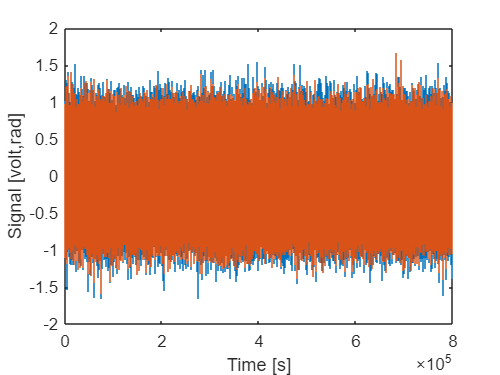


% Plot the measurement
figure(); clf();
stairs(u); hold on; stairs(d);
xlabel('Time [s]'); ylabel('Signal [volt,rad]');
hold off

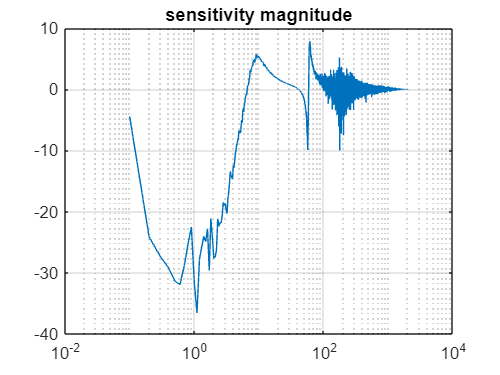


%window settings
min_freq = 0.1; %[Hz/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds

nfft = round(windowsize/stepsize); %window size in data points 
n_overlap = round(nfft/5);

%Tf estimate
[Sud, F] = tfestimate(d,u,hann(nfft),n_overlap,nfft,fs); %cross spectral power density
Sdd = pwelch(d,hann(nfft)); %spectral power disturbance
Suu = pwelch(u,hann(nfft)); %spectral power input
%S =  Sud./Sdd; %sensitivity function
S = Sud;

figure()
semilogx(F,mag2db(abs(S)))
title("sensitivity magnitude")
grid on; hold off

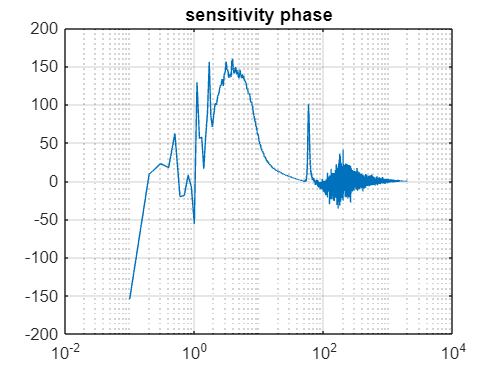


figure()
semilogx(F,angle(S)/pi*180)
title('sensitivity phase')
grid on; hold off

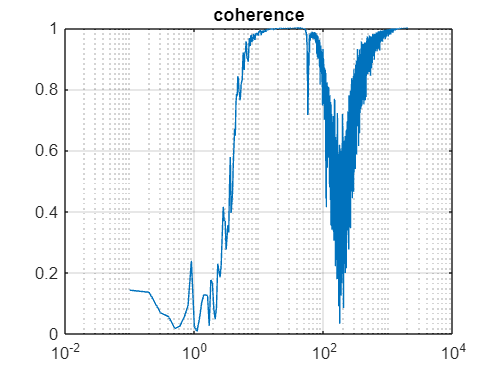


%plotting coherence 
figure()
[coherence_ry, f] = mscohere(d,u,hann(nfft),n_overlap,nfft,fs);
semilogx(f,coherence_ry)
title('coherence')
grid on; hold off

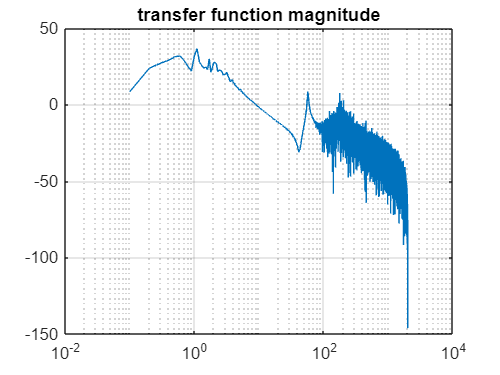

   
%plotting open loop transfer function
L = 1./S - 1;
figure()
semilogx(F,mag2db(abs(L)))
title('transfer function magnitude')
grid on; hold off

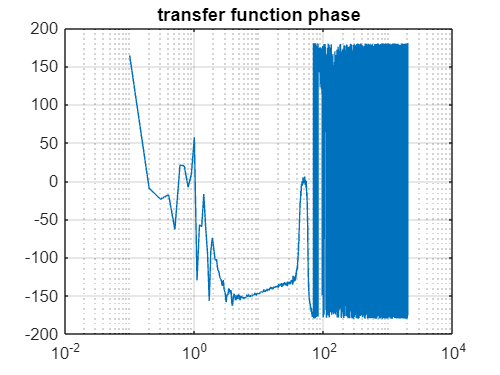


figure()
semilogx(F,angle(L)/pi*180)
title('transfer function phase')
grid on; hold off

sys = frd(L,F)

sys =
 
    Frequency(rad/s)            Response       
    ----------------            --------       
           0.0000       -2.039e+00 + 0.000e+00i
           0.1000       -2.509e+00 + 7.168e-01i
           0.2000        1.493e+01 - 2.481e+00i
           0.3000        2.060e+01 - 9.008e+00i
           0.4000        2.648e+01 - 8.634e+00i
           0.5000        1.635e+01 - 3.267e+01i
           0.6000        3.593e+01 + 1.376e+01i
           0.7000        2.508e+01 + 8.941e+00i
           0.8000        1.713e+01 - 2.387e+00i
           0.9000        1.221e+01 + 1.843e+00i
           1.0000        2.071e+01 + 3.203e+01i
           1.1000       -4.348e+01 - 5.208e+01i
           1.2000        1.297e+01 - 2.023e+01i
           1.3000        9.484e+00 - 1.637e+01i
           1.4000        1.434e+01 - 4.418e+00i
           1.5000        8.150e+00 - 1.505e+01i
           1.6000       -1.058e+00 - 1.378e+01i
           1.7000       -2.867e+01 - 1.244e+01i
           1.8000       -1.404e-

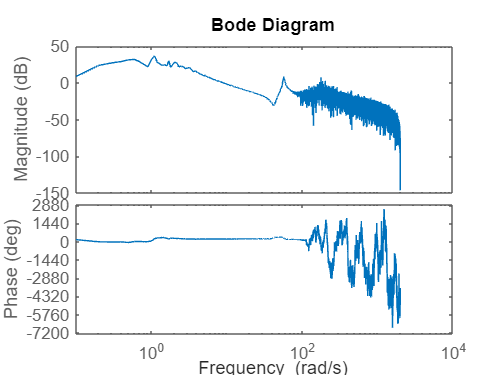

bode(sys)

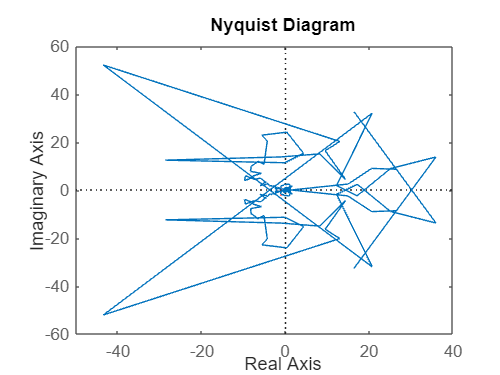

nyquist(sys)